# Humidity

Vlažnost ali *humidity *je definirana kot koncentracija vode v ozračju. Njena enota je $g/m^3$. Graf predsavljen v navodilih naloge (oziroma grah, ki ga moram ustvariti) predstavlja **največjo koncentracijo vode, ki jo lahko ozračje premore pri različnih temperaturah (absolute vapour density).**

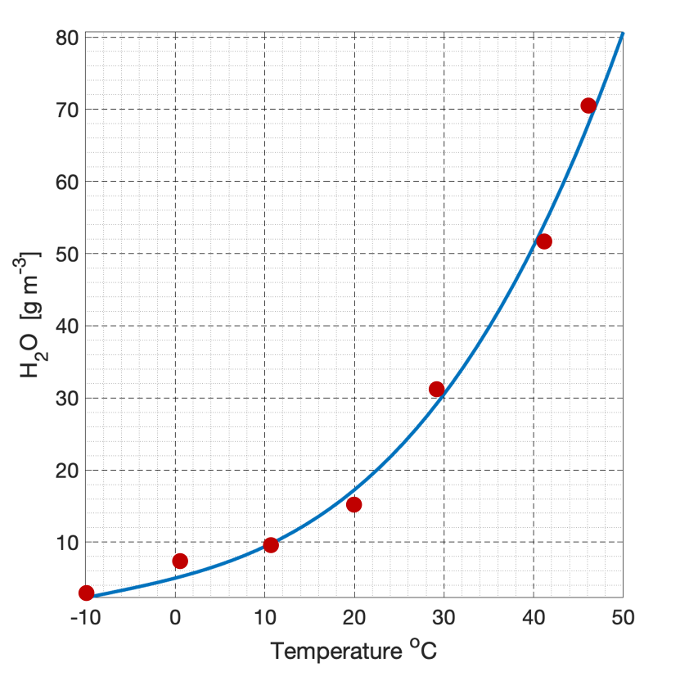

Relativna vlažnost ali *relative humidity *je delež, ki primerja vlažnost zraka pri neki temperaturi z maksimalno (absolutno) možno vlažnostjo.


$$\text{relative humidity} = \frac{\text{current humidity}}{\text{absolute vapour density}} \times 100$$


#### * Derive empirical function temperature vs saturated vapour density*

#### *read data points from graph (at temperature -10, 0, 10, 20, 30, 40, 45°C)*

#### *and fit function through data points*

Razberemo podatke iz grafa.

T =   [-10; 0; 10; 20; 30; 40; 45];  % temperature
SVD = [ 1;  7; 9;  15; 31; 42; 70];  % saturated (absolute) vapour density

S funkcijo `fit` *fittamo *podatke neki krivulji (glede na zgornjo sliko bi bile rdeče točke naši podatki `T` in `SVD`, priležna krivulja pa modra krivulja z grafa).

Funkcija vrne `fit` objekt z večimi komponentami. Nas zanimata predvsem prva dva.

- komponenta s podatki, ki opisujejo, kako dobro se moja funkcija prilega podanim točkam

- komponenta s funkcijo in vrednostmi koeficientov

[fu, fo] = fit(T, SVD, 'poly3');
fo

fo = struct with fields:
           sse: 87.4075
       rsquare: 0.9758
           dfe: 3
    adjrsquare: 0.9515
          rmse: 5.3978


Pomembne so predvsem vrednosti 

- `rmse: 5.3978`, ki opisuje kakšno napako v povprečju pričakovati za vsako točko (manjše vrednosti $\Rightarrow$ boljše prileganje). Vrednost `5.3978` pomeni, da se bo v povprečju izračunana vrednost razlikovala za $\approx 5.4$ enot, kar ni tako veliko glede na razpon podatkov (med 1 in 70).

- `rsquare: 0.9758`, ki opisuje varianco podatkov (kako so razpršeni). Varianca $\approx 97\%$ pomeni, da se moja funkcija zelo dobro prilega podatkom.

fu

fu =      Linear model Poly3:
     fu(x) = p1*x^3 + p2*x^2 + p3*x + p4
     Coefficients (with 95% confidence bounds):
       p1 =   0.0008012  (-0.0007845, 0.002387)
       p2 =    -0.01552  (-0.1013, 0.07024)
       p3 =      0.3927  (-0.6131, 1.398)
       p4 =       7.031  (-5.266, 19.33)

Iz tu dobimo našo funkcijo in priležne koeficiente.

coefv = coeffvalues(fu);
p1 = coefv(1);
p2 = coefv(2);
p3 = coefv(3);
p4 = coefv(4);
f = @(x) p1.*x.^3 + p2.*x.^2 + p3.*x + p4;

Zdaj lahko naredimo graf tako kot je predstavljen zgoraj.

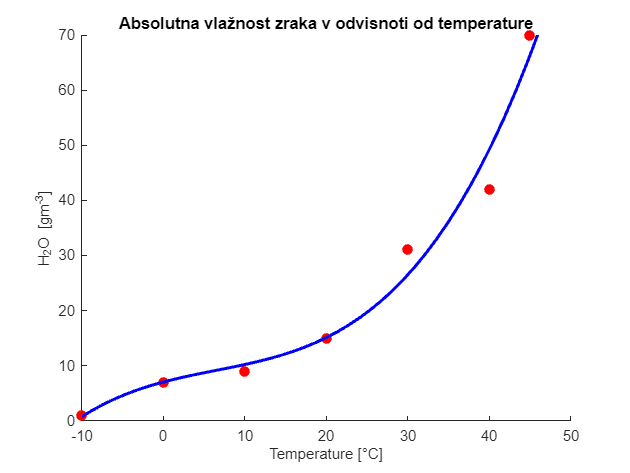

figure
scatter(T, SVD, 50, 'red', 'filled');  % size, color, filled
hold on
fplot(f, 'LineWidth', 2, 'Color', 'blue')
ylabel('H_2O [gm^{-3}]','FontSize',10);
xlabel('Temperature [°C]','FontSize',10);
title('Absolutna vlažnost zraka v odvisnoti od temperature');

#### *Write a Matlab script that calculates relative humidity, absolute vapour density and temperature.  The user should enter two parameters and the third parameter should be calculated by the Matlab  script. *

#### *1) relative humidity inputs: absolute vapour density and temperature; output is relative humidity *

#### *2) absolute vapour density inputs: relative humidity and temperature; output is absolute vapour density *

#### *3) temperature  inputs: absolute vapour density and relative humidity; output is temperature*

Primera 1 in 2 sta precej *straightforward. *Dobimo input od userja in zračunamo relativno vlažnost ali absolutno vlažnost preko enačbe v uvodu, tako da najprej s funkcijo izračunamo vrednost absolutne vlažnosti zraka.Primer 3 je malo bolj kompleksen primer, ker moramo najti inverzno funkcijo. Uporabil bom funckijo `roots`, ki mi bo vrnila ničle moje funkcije glede na koeficiente in podano vrednost. 

**Primer: **to je naša enačba za absolutno vlažnost zraka:

#### 
$$AVD = p_1 T^3 + p_2 T^2 + p_3 T + p_4$$


Za podano `AVD` vrednost postane enačba:

#### 
$$p_1 T^3 + p_2 T^2 + p_3 T + (p_4 - AVD) = 0$$


Koeficiente te enačbe uporabimo v funkciji `roots`, da dobimo ničle funkcije, ki jih lahko nato uporabimo za izračun temperature. Paziti moramo, da se znebimo imaginarnih vrednosti. To naredimo tako, da filtriramo rezultate z `imag(X) == 0`. Funkcija `imag` vrne imaginarni del od `X; `vzamemo samo tiste, katerih imaginarni del je enak 0.Prav tako bom zoožal izbor le na vrednosti med `min` in `max` vrednostjo temperature v podatkih, saj te vrednosti lahko poračunamo z večjo točnostjo, kot tiste, ki se nahajajo izven tega intervala.

minT = min(T);
maxT = max(T);

Npr. za `AVD = 30.`

coeffs = [p1, p2, p3, p4 - 30];
roots_T = roots(coeffs)

roots_T =   32.0245 + 0.0000i
  -6.3244 +29.2432i
  -6.3244 -29.2432i


roots_T(imag(roots_T) == 0 & roots_T >= minT & roots_T <= maxT)

ans = 32.0245

Končni program je v datoteki `humidity_calculator.m`.